# CNN

clc; clear; close all;

## 1.CNN Model

**Load Data**

The built-in 'Digit(MNIST)' dataset for CNN classification

% Data directory
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

% Load image as a datastorage format
% 10000 files included
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

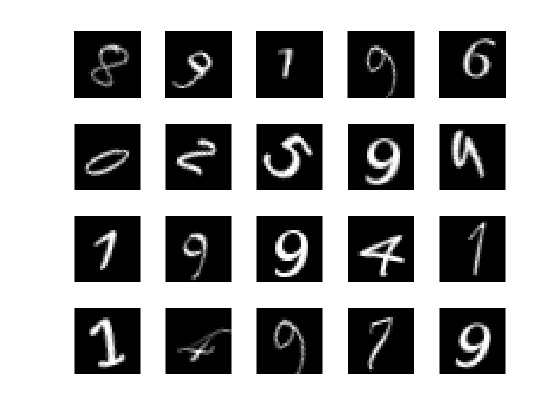

% Plot the data using imshow function
% Pick the 20 random image
figure
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

% Read image using readimage function
% Image has size of 28 pixel x 28 pixel
img = readimage(imds,1);
size(img)

ans =     28    28


**Data Sorting**

Split the image data storage into train and validation set

% Check the label distribution
countEachLabel(imds)

ans = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


% split 750 training, 250 test for each label randomly
n_train_files = 750;
[imds_train,imds_validation] = splitEachLabel(imds,n_train_files,'randomize');

**Layer Design**

Design the neural Network Architecture

layers = [
    % input layer
    % set dimension by image size
    imageInputLayer([28 28 1])
    
    % convolution layer1
    % 3 x 3 filter
    % 8 filter
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % 2 x 2 pool size
    % stride 2 (without overlap)
    maxPooling2dLayer(2,'Stride',2)
    
    % convolution layer2
    % 3 x 3 filter
    % 16 filter
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % 2 x 2 pool size
    % stride 2 (without overlap)
    maxPooling2dLayer(2,'Stride',2)
    
    % convolution layer3
    % 3 x 3 filter
    % 32 filter
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % output layer
    % classification using softmax function
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

**Training Parameters**

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imds_validation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

**Train CNN**

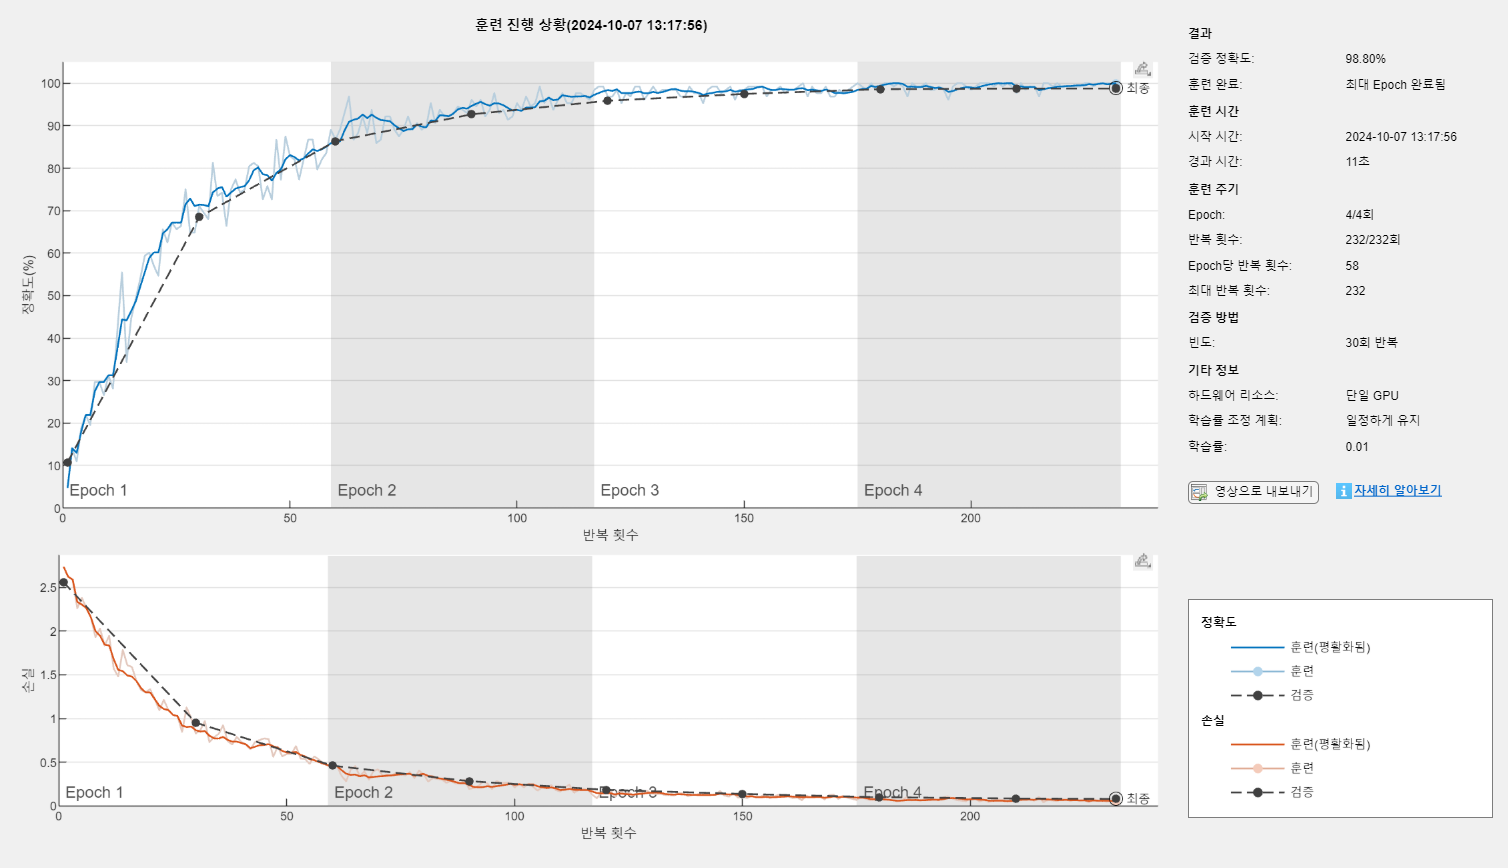

net = trainNetwork(imds_train,layers,options);

**Test the trained CNN using validation set**

y_pred = classify(net,imds_validation);
y_true = imds_validation.Labels;

acc = num2str(100*sum(y_pred == y_true)/numel(y_true));
fprintf('The classification accuracy is %s %% \n',acc)

The classification accuracy is 98.8 % 


## **2. Extract the output from each layer**

% select random image
img = readimage(imds,randperm(10000,1));

figure;
subplot(1,4,1)
imagesc(img)
colormap gray
title('Input')
sgtitle('Filter Output')

% index of filter
% select one filter to check the output
i_in = 1;
i_out = 1;
X = img;

**First Layer**

% Extract the weight and bias from first layer
W = net.Layers(2).Weights;
b = net.Layers(2).Bias;


% Convolution
conv_output1 = [];
conv_output1(:,:) = conv2(X,W(:,:,1,i_in),'valid');
conv_output1(:,:) = conv_output1(:,:)+b(:,:,i_in);


% Relu for first filter
output1 = conv_output1(:,:).*double(conv_output1(:,:)>0);

subplot(1,4,2)
imagesc(output1)
title('Output of Layer1')


% pooling kernel size and stride
k = 2; s = 2;

[rows, cols] = size(output1);
out_rows = floor((rows - k)/s) + 1;
out_cols = floor((cols - k)/s) + 1;


% max pooling
pool1 = [];
for i = 1:s:cols-k+1
    for j = 1:s:cols-k+1
        % Extract the current block
        block = output1(i:i+k-1, j:j+k-1);
        pool1(ceil(i/s), ceil(j/s)) = max(block(:));
    end
end

% get pooled output
X = pool1;

**Second Layer**

% Extract the weight and bias from second layer
W = net.Layers(6).Weights;
b = net.Layers(6).Bias;


% Convolution
conv_output2 = [];
conv_output2(:,:) = conv2(X,W(:,:,i_in,i_in),'valid');
conv_output2(:,:) = conv_output2(:,:)+b(:,:,i_in);


% Relu for second filter
output2 = conv_output2(:,:).*double(conv_output2(:,:)>0);

subplot(1,4,3)
imagesc(output2)
title('Output of Layer2')


% pooling kernel size and stride
k = 2; s = 2;

[rows, cols] = size(output2);
out_rows = floor((rows - k)/s) + 1;
out_cols = floor((cols - k)/s) + 1;


% max pooling
pool2 = [];
for i = 1:s:cols-k+1
    for j = 1:s:cols-k+1
        % Extract the current block
        block = output2(i:i+k-1, j:j+k-1);
        pool2(ceil(i/s), ceil(j/s)) = max(block(:));
    end
end

% get pooled output
X = pool2;

**Third Layer**

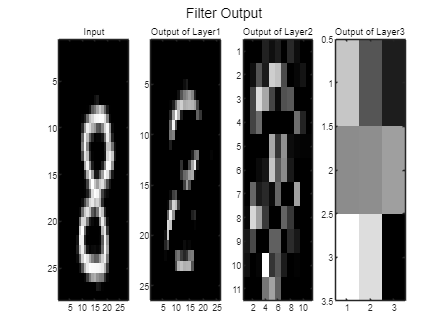

% Extract the weight and bias from third layer
W = net.Layers(10).Weights;
b = net.Layers(10).Bias;


% Convolution
conv_output3 = [];
conv_output3(:,:) = conv2(X,W(:,:,i_in,i_out),'valid');
conv_output3(:,:) = conv_output3(:,:)+b(:,:,i_out);


% Relu for third filter
output3 = conv_output3(:,:).*double(conv_output3(:,:)>0);

subplot(1,4,4)
imagesc(output3)
title('Output of Layer3')

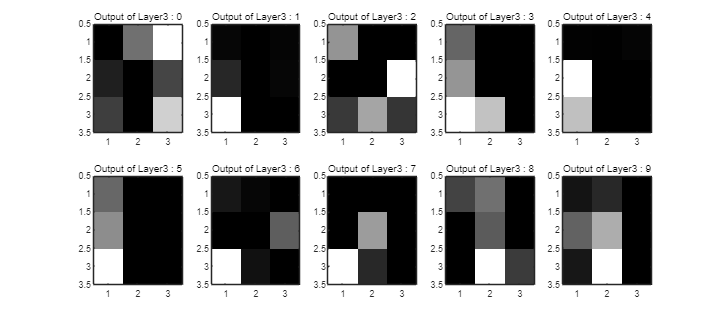

figure('Position',[100 100 900 400])
for num = 1:10
    eval(['img' num2str(num-1) ' = readimage(imds,randperm(1000,1)+1000*(' num2str(num-1) '));'])

    % index of filter
    % select one filter to check the output
    i_in = 8;
    i_out = 18;

    eval(['X = img' num2str(num-1) ';'])
    
    % Extract the weight and bias from first layer
    W = net.Layers(2).Weights;
    b = net.Layers(2).Bias;
    
    % Convolution
    conv_output1 = [];
    conv_output1(:,:) = conv2(X,W(:,:,1,i_in),'valid');
    conv_output1(:,:) = conv_output1(:,:)+b(:,:,i_in);
    
    % Relu for first filter
    output1 = conv_output1(:,:).*double(conv_output1(:,:)>0);

    % pooling kernel size and stride
    k = 2; s = 2;
    
    [rows, cols] = size(output1);
    out_rows = floor((rows - k)/s) + 1;
    out_cols = floor((cols - k)/s) + 1;
    
    % max pooling
    pool1 = [];
    for i = 1:s:cols-k+1
        for j = 1:s:cols-k+1
            % Extract the current block
            block = output1(i:i+k-1, j:j+k-1);
            pool1(ceil(i/s), ceil(j/s)) = max(block(:));
        end
    end
    
    % get pooled output
    X = pool1;
    
    % Extract the weight and bias from second layer
    W = net.Layers(6).Weights;
    b = net.Layers(6).Bias;
    
    % Convolution
    conv_output2 = [];
    conv_output2(:,:) = conv2(X,W(:,:,i_in,i_in),'valid');
    conv_output2(:,:) = conv_output2(:,:)+b(:,:,i_in);
    
    % Relu for second filter
    output2 = conv_output2(:,:).*double(conv_output2(:,:)>0);
        
    % pooling kernel size and stride
    k = 2; s = 2;
    
    [rows, cols] = size(output2);
    out_rows = floor((rows - k)/s) + 1;
    out_cols = floor((cols - k)/s) + 1;
    
    % max pooling
    pool2 = [];
    for i = 1:s:cols-k+1
        for j = 1:s:cols-k+1
            % Extract the current block
            block = output2(i:i+k-1, j:j+k-1);
            pool2(ceil(i/s), ceil(j/s)) = max(block(:));
        end
    end
    
    % get pooled output
    X = pool2;
    
    % Extract the weight and bias from third layer
    W = net.Layers(10).Weights;
    b = net.Layers(10).Bias;
    
    % Convolution
    conv_output3 = [];
    conv_output3(:,:) = conv2(X,W(:,:,i_in,i_out),'valid');
    conv_output3(:,:) = conv_output3(:,:)+b(:,:,i_out);
    
    % Relu for third filter
    eval(['out' num2str(num-1) ' = conv_output3(:,:).*double(conv_output3(:,:)>0);'])
    
    subplot(2,5,num)
    eval(['imagesc(out' num2str(num-1) ')'])
    colormap gray
    title(['Output of Layer3 : ' num2str(num-1)])
end